# Hopping in Legged Systems-Modeling and Simulation for the Two-Dimensional One-Legged Case

Kirill Zharkov

clear, clc;

#### Parameters


body_mass = 10; % Kg
leg_mass = 1; % Kg
spring_stifness = 10000; % N/m
spring_damping = 50; % N/m*s

CoM_distance_body = 0.2; %m
foot_r = 0.01; %m
leg_length = 0.25; %m
 

world_plane_size = 10; % Square
start_pos_x = 0; %m
start_pos_y = 0; %m
start_h = 0.55; %m
start_speed = 0.0; %m/s


mdl = 'hopper';
open(mdl);
out = sim(mdl);

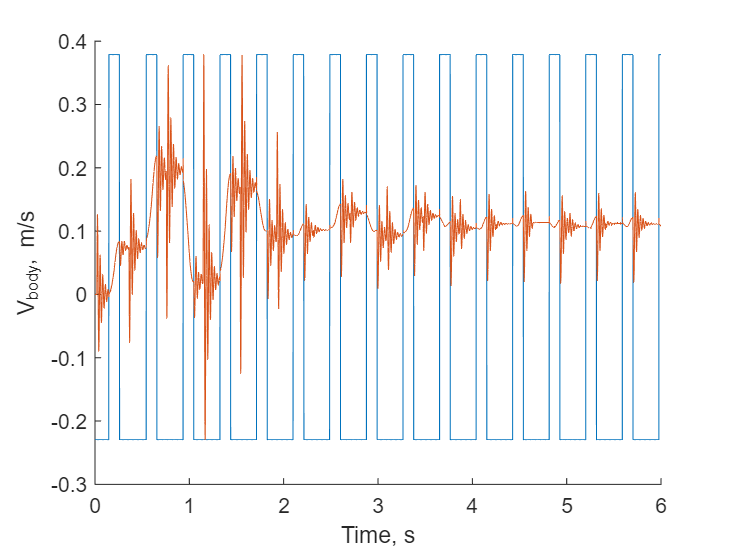

 

master_graph = out.simout.linear_vel;
min_graph = min(master_graph.Data);
max_graph = max(master_graph.Data);
def_min_max = max_graph - min_graph;

normalize_plot = out.simout.is_contact.Data;
normalize_plot = normalize_plot*def_min_max;
normalize_plot = normalize_plot + min_graph;

figure;
hold on;
xlabel('Time, s')
ylabel('V_{body}, m/s')
plot(out.simout.is_contact.Time, normalize_plot(:,1));
plot(out.simout.is_contact.Time, master_graph.Data(:,1));

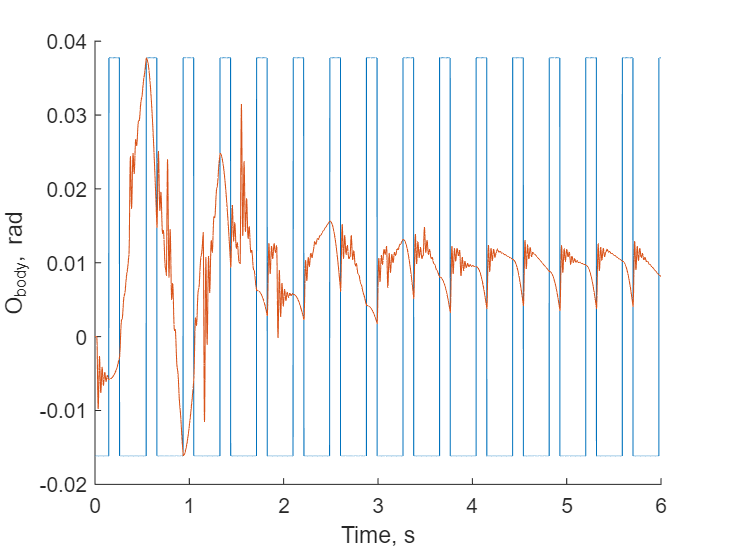

master_graph = out.simout.pos_o_body;
min_graph = min(master_graph.Data);
max_graph = max(master_graph.Data);
def_min_max = max_graph - min_graph;

normalize_plot = out.simout.is_contact .Data;
normalize_plot = normalize_plot*def_min_max;
normalize_plot = normalize_plot + min_graph;

figure;
hold on;
xlabel('Time, s')
ylabel('O_{body}, rad')
plot(out.simout.is_contact.Time, normalize_plot(:,1));
plot(out.simout.is_contact.Time, master_graph.Data(:,1));

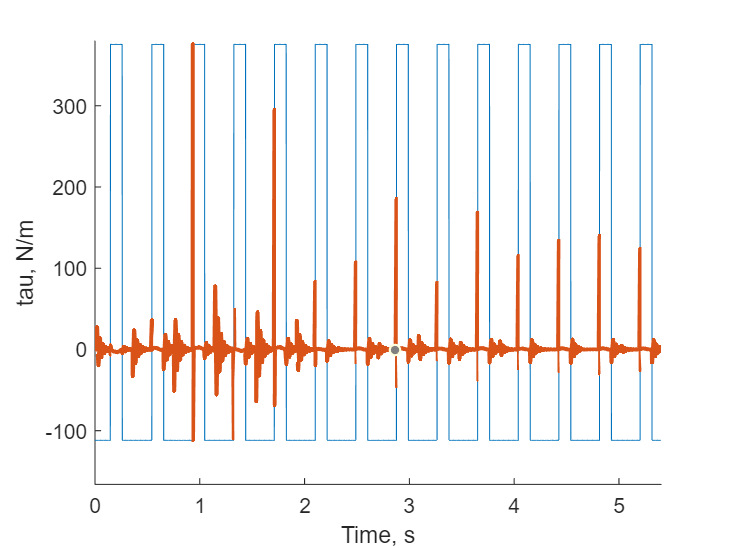

master_graph = out.simout.tau;
min_graph = min(master_graph.Data);
max_graph = max(master_graph.Data);
def_min_max = max_graph - min_graph;

normalize_plot = out.simout.is_contact.Data;
normalize_plot = normalize_plot*def_min_max;
normalize_plot = normalize_plot + min_graph;

figure;
hold on;
xlabel('Time, s');
ylabel('tau, N/m');
 
%area(out.simout.is_contact.Time, normalize_plot(:,1),'FaceAlpha',0.1,'FaceColor','blue','AlignVertexCenters', 'off');
plot(out.simout.is_contact.Time, normalize_plot(:,1));
plot(master_graph.Time, master_graph.Data(:,1),'LineWidth',2)

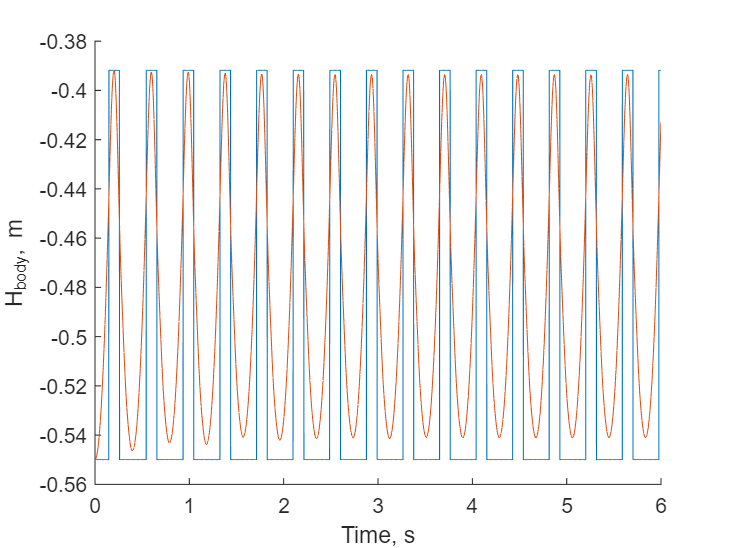

master_graph = out.simout.pos_z_body;
min_graph = min(-master_graph.Data);
max_graph = max(-master_graph.Data);
def_min_max = max_graph - min_graph;

normalize_plot = out.simout.is_contact.Data;
normalize_plot = normalize_plot*def_min_max;
normalize_plot = normalize_plot + min_graph;

figure;
hold on;
xlabel('Time, s')
ylabel('H_{body}, m')
plot(out.simout.is_contact.Time, normalize_plot(:,1));
plot(out.simout.is_contact.Time, -master_graph.Data(:,1));